# PID Controller Design and Analysis 

# Assignment 2

## Problem 1: Basic Plant Response Analysis

### Given Plant 

num = [100];
den = [1 15 50];
open_loop_tf = tf(num,den)


open_loop_tf =
 
        100
  ---------------
  s^2 + 15 s + 50
 
Continuous-time transfer function.


### Open loop Analysis

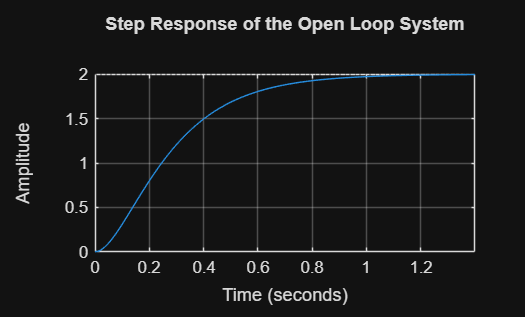

step(open_loop_tf)                                % Function for plotting step response
grid on                                           % Shows grids
title('Step Response of the Open Loop System');

fprintf("Details of the step plot")

Details of the step plot


stepinfo(open_loop_tf)                             % Function to get the details in the plot.

ans = struct with fields:
         RiseTime: 0.5180
    TransientTime: 0.9200
     SettlingTime: 0.9200
      SettlingMin: 1.8045
      SettlingMax: 1.9983
        Overshoot: 0
       Undershoot: 0
             Peak: 1.9983
         PeakTime: 1.5565



y_infinity = dcgain(open_loop_tf);                 % y value at infinity
error_stedystate = 1-y_infinity                        % Stedy State error = 1 - y value at infinity

error_stedystate = -1

- Steady State error does not exsist as there is no feedback machanism in the open loop.

- Low accuracy because it is an open loop system.

### P controller Design 

Kp = 0.5;                                            % Given 
gained_tf = Kp*open_loop_tf;                         % Multiplying the proportionlity gain so that we can make the closed loop transfer function .
closed_loop_tf = feedback(gained_tf,1)               % Closed loop Transfer function


closed_loop_tf =
 
         50
  ----------------
  s^2 + 15 s + 100
 
Continuous-time transfer function.


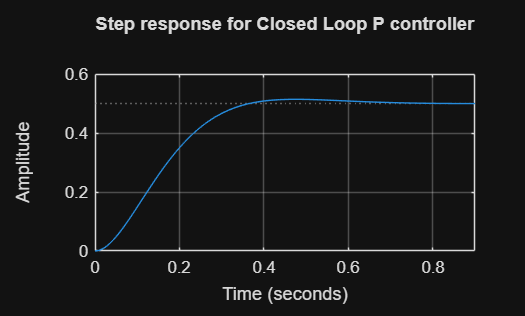


step(closed_loop_tf)                                 % Getting the Closed Loop Step Response
grid on
title("Step response for Closed Loop P controller")


fprintf(" performance metrics ")

 performance metrics 

stepinfo(closed_loop_tf)                             % performance metrics 

ans = struct with fields:
         RiseTime: 0.2288
    TransientTime: 0.5743
     SettlingTime: 0.5743
      SettlingMin: 0.4524
      SettlingMax: 0.5142
        Overshoot: 2.8369
       Undershoot: 0
             Peak: 0.5142
         PeakTime: 0.4728



fprintf(" Stedy State Error for Closed loop system")

 Stedy State Error for Closed loop system

Y_ss = dcgain(closed_loop_tf);                       % Value of y at infinity
e_ss = 1-Y_ss                                        % Steady state error for closed loop system

e_ss = 0.5000

- Steady state error does not exsists in case of open loop  because it does not have any feedback mechanism , in closed loop systems the output is decided by the error so to maintain an output some error must be present .

- when there is proportionality gain the transfer function for the closed loop becomes :

                     G(s) : Plant or OLTF

                     Kp : proportionality gain 

                    CLTF = $\frac{\textrm{Kp}\times G\left(s\right)}{1+\textrm{Kp}\times G\left(s\right)}$     

                 Here I mentioned the $\textrm{Kp}\times G\left(s\right)$ as gained transfer function ( if open loop )

### PI Controller Design:

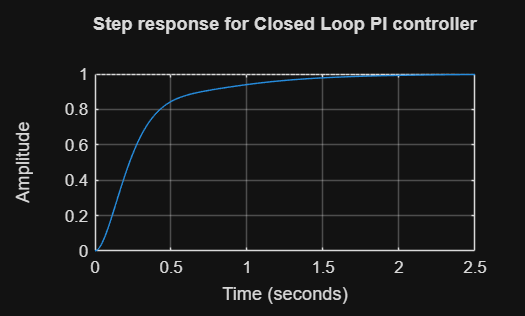

Kp = 0.5 ;
Ki = 1.5 ;
PI = pid(Kp,Ki,0);
closed_loop_pi_tf = feedback(PI * open_loop_tf, 1);    % Closed loop transfer function with PI controller
step(closed_loop_pi_tf)
title("Step response for Closed Loop PI controller")
grid on 


fprintf(" performance metrics ")

 performance metrics 

stepinfo(closed_loop_pi_tf)                             % performance metrics 

ans = struct with fields:
         RiseTime: 0.6278
    TransientTime: 1.5377
     SettlingTime: 1.5377
      SettlingMin: 0.9016
      SettlingMax: 0.9981
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9981
         PeakTime: 2.6861



fprintf(" Stedy State Error for Closed loop system")

 Stedy State Error for Closed loop system

Y_ss = dcgain(closed_loop_pi_tf);                       % Value of y at infinity
e_ss = 1-Y_ss 

e_ss = 0

Observations :

- The value of Steady state error declined to zero.

- Overshoot became zero.

- Accurcy increased at the steady state in PI.

- The time taken to achive the Steady state value is more in PI controller .

Integral Action :

- In case of P-only controller  only a gain(Kp) is added to the input and a feedback is added to make it closed loop.

- In PI controller a gain(Kp) with a integrator is added whose coieffcient is Ki.

- The variable PI in code converts input to:

                             C(s) = Kp+$\frac{\textrm{Ki}}{s}$

                             So, now gained input becomes = G(s)$\times$C(s)

                             and the closed loop Transfer function : $\frac{C\left(s\right)\times G\left(s\right)}{1+C\left(s\right)\times G\left(s\right)}$     

Effects of integral Action :

- If steady state error exsists then integral keeps increasing and its increase leads to increase in the OUTPUT.

- the system cannot settle until the error becomes zero.

- High accuracy of controller .

### PID Controller Tuning:

C = pidtune(open_loop_tf,'PID')                                   % This function is used to automatically tune the pid controller 


C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.993, Ki = 4.84, Kd = 0.0442
 
Continuous-time PID controller in parallel form.


fprintf("Tuned PID Controller Parameters:\n");

Tuned PID Controller Parameters:


disp(C);                                                          % to display controller properties 

  pid with properties:

              Kp: 0.9931
              Ki: 4.8444
              Kd: 0.0442
              Tf: 0
        IFormula: ''
        DFormula: ''
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



closed_loop_pid_tf = feedback(C*open_loop_tf,1)


closed_loop_pid_tf =
 
     4.421 s^2 + 99.31 s + 484.4
  ---------------------------------
  s^3 + 19.42 s^2 + 149.3 s + 484.4
 
Continuous-time transfer function.


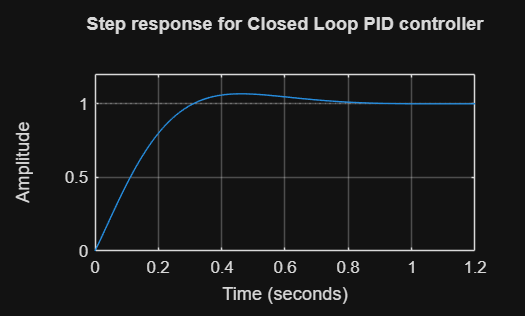


step(closed_loop_pid_tf)
title("Step response for Closed Loop PID controller")
grid on 


stepinfo(closed_loop_pid_tf)

ans = struct with fields:
         RiseTime: 0.2225
    TransientTime: 0.7237
     SettlingTime: 0.7237
      SettlingMin: 0.9053
      SettlingMax: 1.0657
        Overshoot: 6.5696
       Undershoot: 0
             Peak: 1.0657
         PeakTime: 0.4604


All the conditions are satisfied by the PID controller with` :`

`              Kp: 0.9931`

`              Ki: 4.8444`

`              Kd: 0.0442`

`The Overshoot is 6.5696 , steady state error is zero and the settling time is 0.72 .`

`As final value of y at infinity is one the steady state error is zero.`

`here , pidtune is function which automatically chooses the values of PID to ensure a good system.`

## Problem 2: Complex Input Tracking

using the same PID controller in problem 1

### Multi-Step Reference:

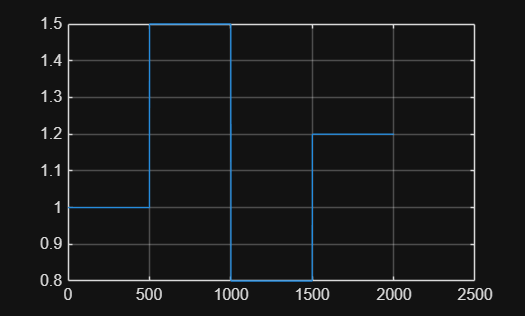

%% Generating the Reference inputs signal
time_vector = 0:0.01:20;             % Time Vector 
r = zeros(size(time_vector));        % Reference Signal
r(time_vector >= 0)  = 1;
r(time_vector >= 5)  = 1.5;                    % Genrating the given input 
r(time_vector >= 10) = 0.8;
r(time_vector >= 15) = 1.2;
plot(r)
grid on

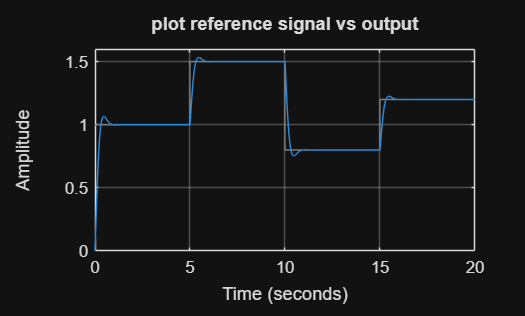


% Simulate the closed-loop PID system response to the reference signal
lsim(closed_loop_pid_tf, r, time_vector)
title(" plot reference signal vs output ")
grid on

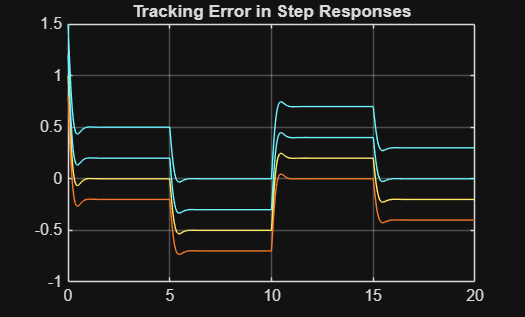


%% Tracking Error is the error between the reference signal and the gained output:
%   error = signal - output
[y,t]=lsim(closed_loop_pid_tf, r, time_vector);      % For getting output values.
error = r - y;                                       % A plot will be better to do representation.
plot(time_vector,error)
title(" Tracking Error in Step Responses ")
grid on

### Ramp Input

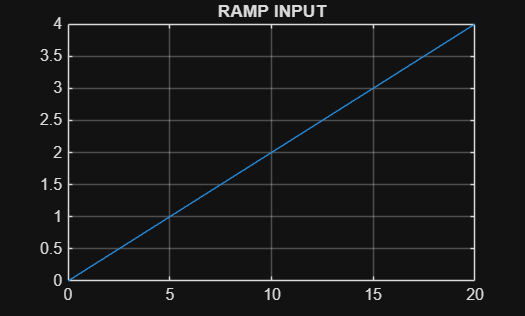

%% Generating the Ramp input
%using predefined time vector
slope = 0.2;
Ramp_input = slope*time_vector;
plot(time_vector,Ramp_input)
title("RAMP INPUT")
grid on

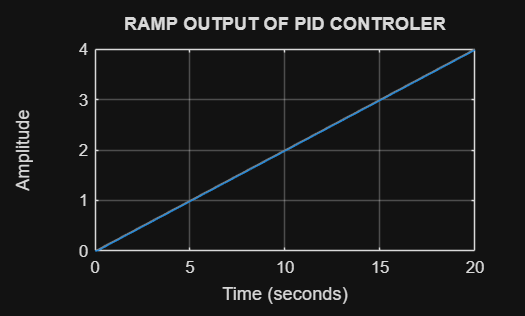


%% Generating the output
lsim(closed_loop_pid_tf,Ramp_input,time_vector)
grid on 
title(" RAMP OUTPUT OF PID CONTROLER ")

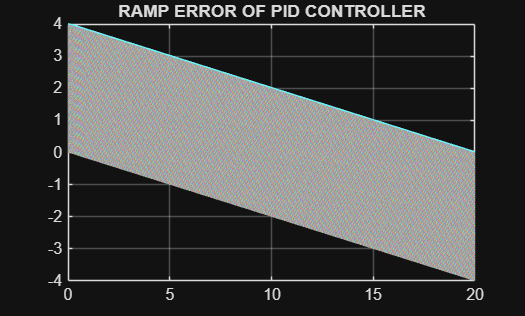


%% ERROR
[y_ramp t] = lsim(closed_loop_pid_tf,Ramp_input,time_vector);
error_ramp = Ramp_input - y_ramp;
plot(time_vector,error_ramp)
grid on
title("RAMP ERROR OF PID CONTROLLER")

### Sinusoidal Reference:

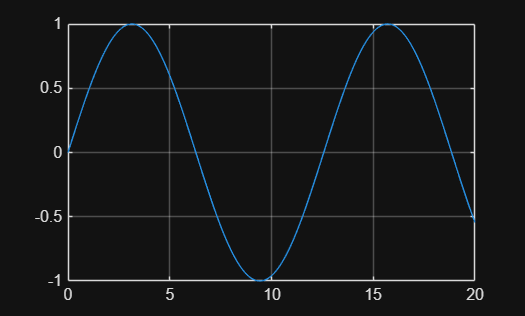

%% Sine wave as input : sine wave has a very chaging and repeting pattern so it is a very good option for checking the controller
input = sin(0.5*time_vector);
plot(time_vector,input)
grid on 

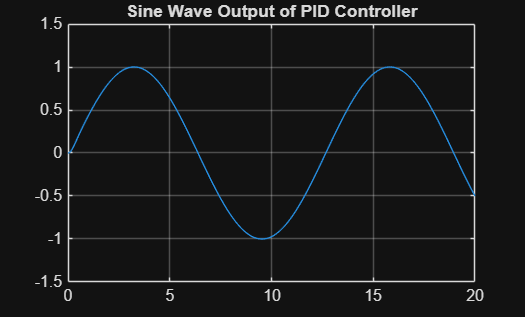


% Simulate the closed-loop PID system response to the sine wave input
[y_sine, t_sine] = lsim(closed_loop_pid_tf, input, time_vector);
plot(t_sine, y_sine)
title("Sine Wave Output of PID Controller")
grid on

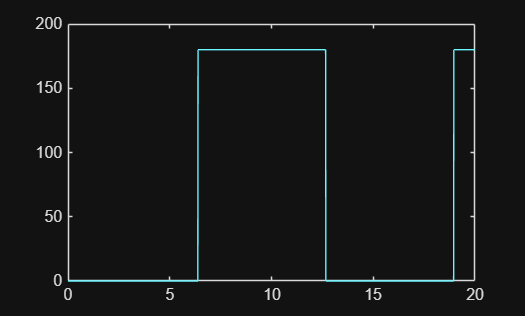


% finding phase
[meg phase] = bode(y_sine,0.5);
plot(time_vector,phase)

% THIS SHOWS THAT THE INPUT AND OUTPUT ARE IN SAME PHASE

## Problem 3: Practical PID Implementation Challenges

% Transfer Function for problem 
num = [50];
den = [1 8 25 20];
transfer_function = tf(num,den)


transfer_function =
 
            50
  -----------------------
  s^3 + 8 s^2 + 25 s + 20
 
Continuous-time transfer function.


### Observing Integral Windup (Without Anti-Windup):

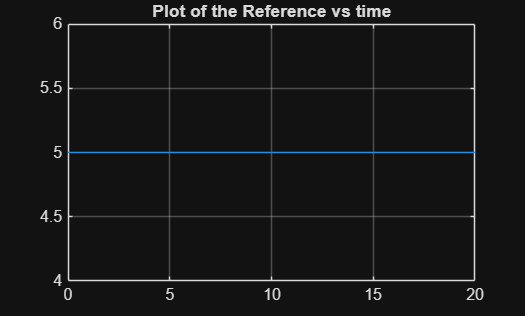

% GIVEN DATA :
Kp = 5;
Ki = 8;

% TIME 
dt = 0.01;
t = 0:dt:20;

% Input 
input = 5*ones(size(t));
% High value to cause saturation

% Limiting value of signal
u_lim = 10;

% PLANT 
plant_ss = ss(transfer_function);
% Creating the matrix for the plant for making input .

% Input and Output 
x = zeros(size(plant_ss.A,1),1);
y = zeros(size(t));

%% Initialization
e_int = 0;

u      = zeros(size(t));   % unsaturated control
u_sat  = zeros(size(t));   % saturated control
I_term = zeros(size(t));   % integral term

% FOR LOOP :
for i = 2:length(t)

    e = input(i)-y(i-1);                   %ERROR
    
    u_p = Kp * e;
    u_i = Ki * e_int ;                   % PI controller
    u(i) = u_p + u_i;
    
    % Apply saturation limits to the control signal
    u_sat(i) = max(min(u(i), u_lim), -u_lim);

    % Integral update
    e_int = e_int + e*dt;
    I_term(i) = e_int;

    % Plant update (uses saturated control)
    xdot = plant_ss.A*x + plant_ss.B*u_sat(i);
    x = x + xdot*dt;

    % Output
    y(i) = plant_ss.C*x;
end 

plot(t,input)
grid on
title(" Plot of the Reference vs time ")

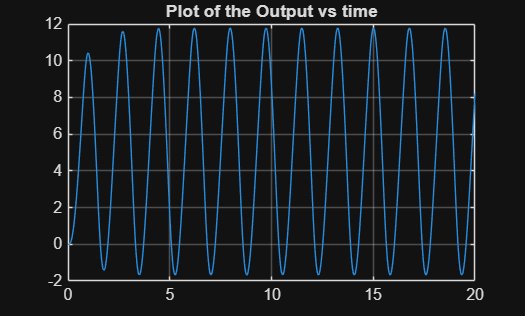


plot(t,y)
grid on
title(" Plot of the Output vs time ")

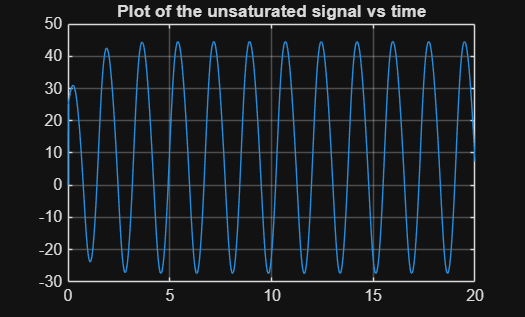


plot(t,u)
grid on
title(" Plot of the unsaturated signal vs time ")

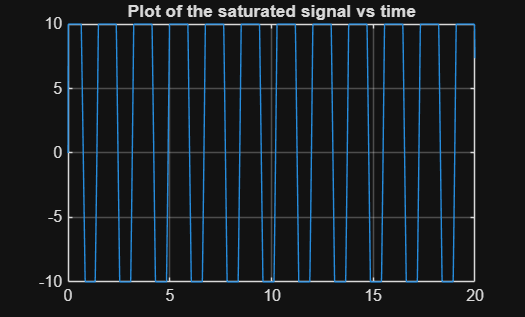


plot(t,u_sat)
grid on
title(" Plot of the saturated signal vs time ")

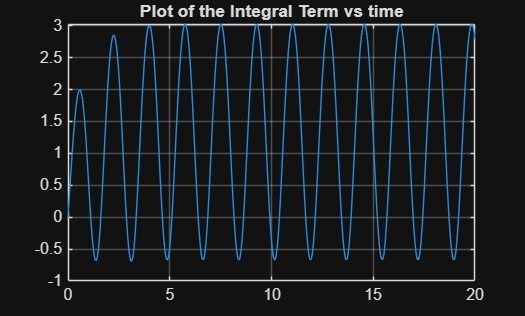


plot(t,I_term)
grid on
title(" Plot of the Integral Term vs time ")

- the large input (5) creates the large error so the output start tending to large values very fast(immidiately) ,so the we can say it becomes saturated almost immidiately at t=0sec.

- Integral term attains its maximum value during the saturation period and then again start decreasing .

- The overshoot becomes high due to this behavior also decreasing the settling time .

### Implementing Anti-Windup:

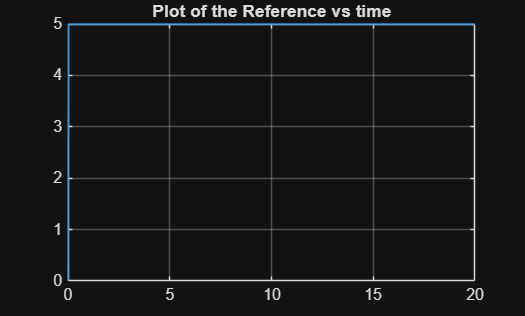

% Generating the CLTF for the controller
Kp = 5;
Ki = 8;
Kt = sqrt(Ki);
C = pid(Kp ,Ki , 0);
gained_Transfer_function = C*transfer_function;
closed_loop_transfer_funstion =  feedback(gained_Transfer_function,1);

% Input 
input = zeros(size(time_vector));
input(time_vector > 0) = 5;

%% BY USING THE CODE GIVEN 
% For anti-windup implementation, use a for-loop simulation
dt = 0.01;
t=0:dt:20;
e_int = 0;                        % integral term
u_lim = 10;
e_prev = 0;

Plant_ss = ss(transfer_function);
x = zeros(size(Plant_ss.A,1),1);
y_aw = zeros(size(t));

u      = zeros(size(t));   % unsaturated control
u_sat_aw  = zeros(size(t));   % saturated control
I_term = zeros(size(t));

% Saturation limit
for i = 2:length(t)

    e = input(i)-y_aw(i-1);                   %ERROR
    
    u_p = Kp * e;
    u_i = Ki * e_int ;                   % PI controller
    u(i) = u_p + u_i;
    
    % Apply saturation limits to the control signal
    u_sat_aw(i) = max(min(u(i), u_lim), -u_lim);

    % Integral update
    e_int = e_int + (e + (u_sat_aw(i)- u(i))/Kt) * dt;
    I_term(i)=e_int;
    
    % Plant update (uses saturated control)
    xdot = Plant_ss.A*x + Plant_ss.B * u_sat_aw(i);
    x = x + xdot*dt;

    % Output
    y_aw(i) = Plant_ss.C*x;
end 

plot(t,input)
grid on
title(" Plot of the Reference vs time ")

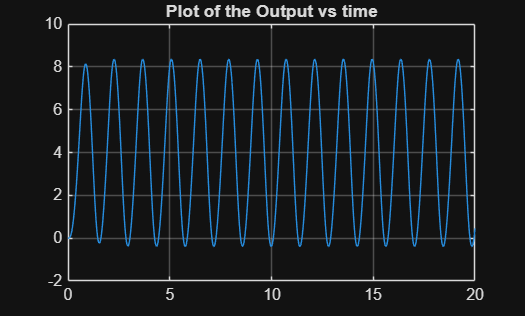


plot(t,y_aw)
grid on
title(" Plot of the Output vs time ")

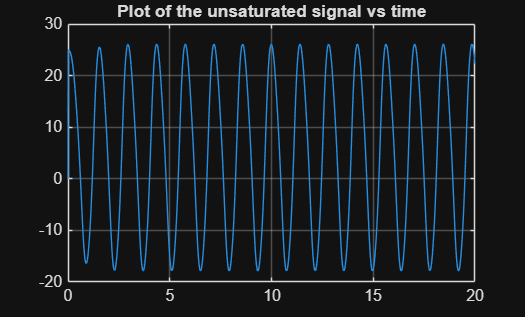


plot(t,u)
grid on
title(" Plot of the unsaturated signal vs time ")

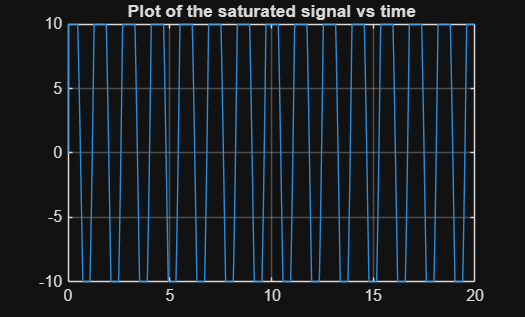


plot(t,u_sat_aw)
grid on
title(" Plot of the saturated signal vs time ")

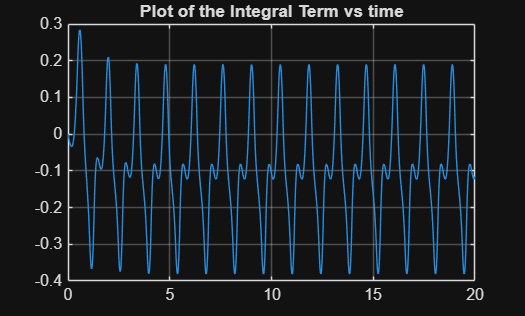


plot(t,I_term)
grid on
title(" Plot of the Integral Term vs time ")

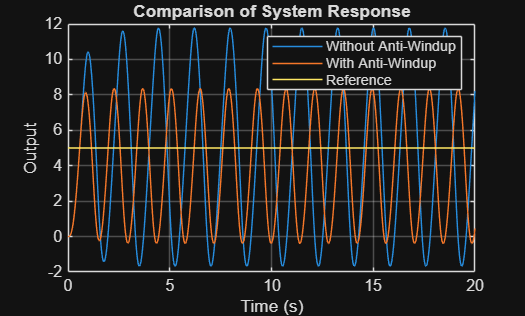


% Comparison of the windup and Antiwindup on the same plot:
figure
plot(t, y)
hold on
plot(t, y_aw)
plot(t, 5*ones(size(t)))   % reference
grid on
legend('Without Anti-Windup','With Anti-Windup','Reference')
xlabel('Time (s)')
ylabel('Output')
title('Comparison of System Response')
hold off


% GENERATING THE STEPINFO FOR THE EXTRACTION OF THE DETAILS :
info_w = stepinfo(y,t);
info_aw = stepinfo(y_aw,t);
% GENERATING THE OVERSHOOT:
Overshoot = [info_w.Overshoot info_aw.Overshoot]

Overshoot = 1.0e+03 *

    0.0434    1.7395


% SETTELING TIME :
SettlingTime = [info_w.SettlingTime; info_aw.SettlingTime]

SettlingTime =    19.9914
   19.9991


% Time spent in saturation:
SatTime_w  = sum(abs(u_sat_aw) >= u_lim) * dt

SatTime_w = 13.9800

SatTime_aw = sum(abs(u_sat_aw) >= u_lim) * dt

SatTime_aw = 13.9800

• Explain how anti-windup prevents excessive integral buildup ?

Answer: 

- The actuator detects when the signal crosses its limiting values and signal attain a steady state value and cannot apply further control efforts .

-  Anti-windup schemes compare the unsaturated control signal with the actual saturated control signal.

- The difference between the saturated and unsaturated control signals is fed back to the integrator to reduce or stop further integration.

- Anti-windup reduces overshoot, shortens settling time, and improves overall stability of the closed-loop system

### Derivative Noise and Low-Pass Filtering:

#### Without Filtering:

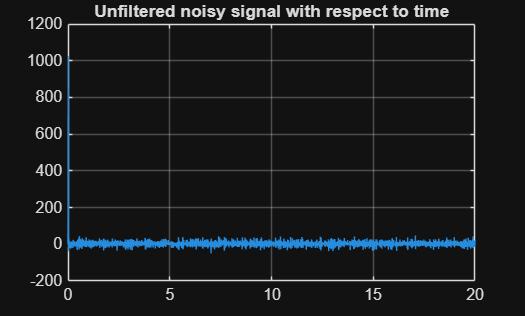

Kp = 5;
Ki = 8;
Kd = 2;

dt = 0.01;
t = 0:dt:20;

Input = 5*ones(size(t));

u_lim_uf = 10;
e_int_uf = 0;
e_prev_uf = 0;

u_sat_uf = zeros(size(t));
u_uf = zeros(size(t));
I_term_uf = zeros(size(t));

plant_ss_uf = ss(transfer_function);
y_uf = zeros(size(t));
x_uf = zeros(size(plant_ss_uf.A,1),1);

for count = 2:length(t)
    y_uf_noisy = y_uf(count-1) + 0.05*randn;

    e_uf = input(count)-y_uf_noisy;

    u_p_uf = Kp * e_uf;
    u_i_uf = Ki * e_int_uf;
    u_d_uf = Kd * (e_uf-e_prev_uf)/dt;
    u_uf(count) = u_p_uf + u_i_uf + u_d_uf;  % Calculate total control signal
    
    u_sat_uf(count) = max(min(u_uf(count), u_lim_uf), -u_lim_uf);  % Apply saturation limits
    
    e_int_uf = e_int_uf + (e_uf + (u_sat_uf(count) - u_uf(count)) / Kt) * dt;  % Update integral term
    
    xdot_uf = plant_ss_uf.A * x_uf + plant_ss_uf.B * u_sat_uf(count);  % Plant dynamics
    x_uf = x_uf + xdot_uf * dt;  % Update state
    y_uf(count) = plant_ss_uf.C * x_uf;  % Output calculation
    e_prev_uf = e_uf;
end

plot(t,u_uf)
grid on 
title(" Unfiltered noisy signal with respect to time ")

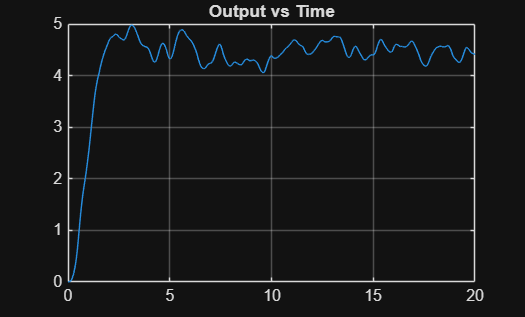


plot(t,y_uf)
grid on 
title(" Output vs Time ")

### With low lass filtering :

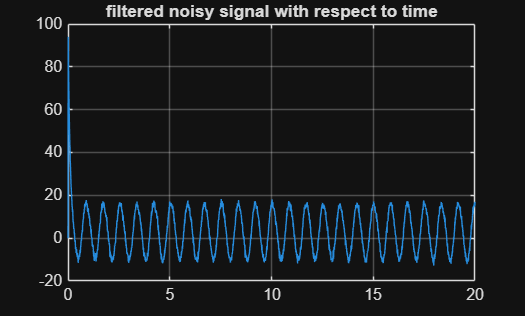

u_lim_f = 10;
e_int_f = 0;
e_prev_f = 0;
e = zeros(size(t));
e_f = zeros(size(t));

u_sat_f = zeros(size(t));
u_f = zeros(size(t));
I_term_f = zeros(size(t));

plant_ss_f = ss(transfer_function);
y_f = zeros(size(t));
x_f = zeros(size(plant_ss_f.A,1),1);

for count = 2:length(t)
    y_f_noisy = y_f(count-1) + 0.05*randn;

    e(count) = input(count)-y_f_noisy;

    tao = 0.1;
    alpha = tao/(tao+dt);

    e_f(count) = alpha*e_f(count-1)+(1-alpha)*(e(count));

    u_p_f = Kp * e_f(count);
    u_i_f = Ki * e_int_f;
    u_d_f = Kd * (e_f(count)-e_prev_f)/dt;
    u_f(count) = u_p_f + u_i_f + u_d_f;  % Calculate total control signal
    
    u_sat_f(count) = max(min(u_f(count), u_lim_f), -u_lim_f);  % Apply saturation limits
    
    e_int_f = e_int_f + (e_f(count) + (u_sat_f(count) - u_f(count)) / Kt) * dt;  % Update integral term
    
    I_term_f(count) = e_int_f;

    xdot_f = plant_ss_f.A * x_f + plant_ss_f.B * u_sat_f(count);  % Plant dynamics
    
    x_f = x_f + xdot_f * dt;  % Update state
    y_f(count) = plant_ss_f.C * x_f;  % Output calculation
    e_prev_f = e_f(count);
end

plot(t,u_f)
grid on 
title(" filtered noisy signal with respect to time ")

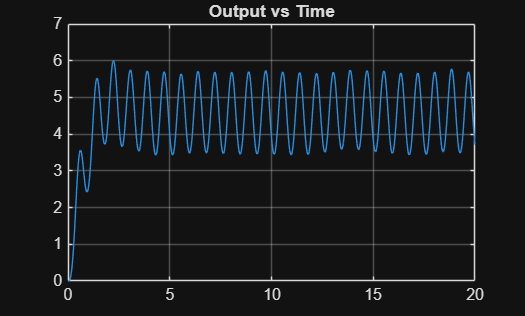


plot(t,y_f)
grid on 
title(" Output vs Time ")

comparisons :

Control Signals

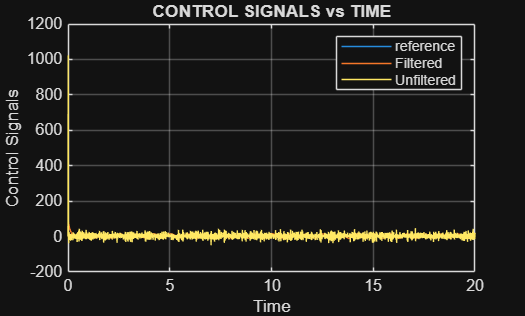

figure
plot(t,input)
hold on 
plot(t,u_f)
plot(t,u_uf)
grid on
ylabel("Control Signals")
xlabel("Time")
title(" CONTROL SIGNALS vs TIME ")
legend("reference",'Filtered ','Unfiltered')
hold off

Output

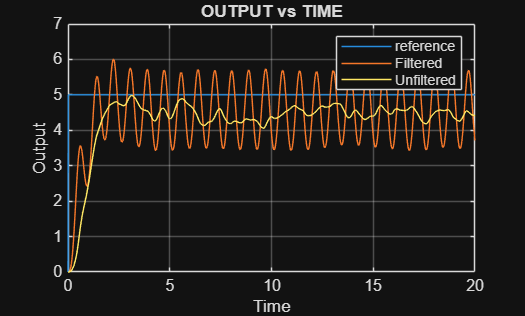

figure
plot(t,input)
hold on 
plot(t,y_f)
plot(t,y_uf)
grid on
ylabel("Output")
xlabel("Time")
title(" OUTPUT vs TIME ")
legend("reference",'Filtered ','Unfiltered')
hold off

Standarad Deviation of the Control Signals:

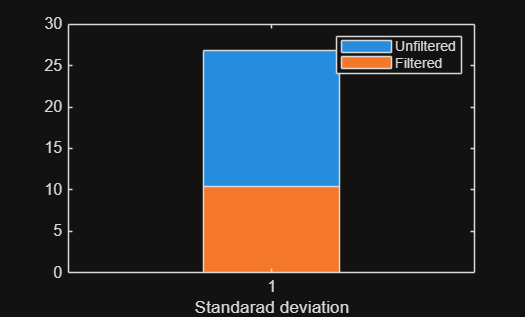

u_f_std = std(u_f);
u_uf_std = std(u_uf);
% As Standard deviation is a absolute value so we cannot plot line 
bar(u_uf_std)
hold on
bar(u_f_std)
xlabel("Standarad deviation")
legend('Unfiltered','Filtered')
hold off

 Explain how filtering reduces noise amplification while maintaining damping effect?

ans:

Low-pass filtering reduces noise amplification by suppressing high-frequency noise before it reaches the derivative action. At the same time, it preserves the damping effect of the PID controller by allowing low-frequency dynamics—responsible for system oscillations—to pass through. This balance results in smoother control action, improved stability, and better real-world performance.

### Complex Trajectory Tracking:

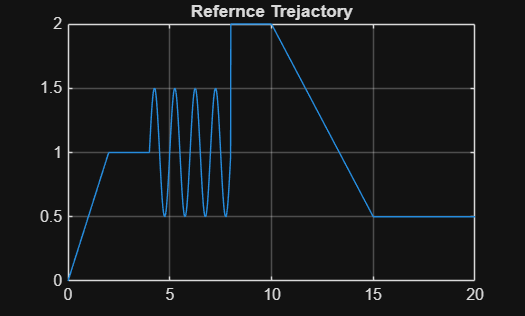

%% GENRATING THE INPUT FOR THE TASK 
% Using the basic for loop anf if else conditions to write the signal.
dt = 0.01;
t  = 0:dt:20;

r = zeros(size(t));

for k = 1:length(t)
    if t(k) < 2
        r(k) = 0.5*t(k);                         % ramp up
    elseif t(k) < 4
        r(k) = 1;                                % hold
    elseif t(k) < 8
        r(k) = 1 + 0.5*sin(2*pi*(t(k)-4));       % oscillation
    elseif t(k) < 10
        r(k) = 2;                                % step up
    elseif t(k) < 15
        r(k) = 2 - 0.3*(t(k)-10);                % ramp down
    else
        r(k) = 0.5;                              % final hold
    end
end

%% BY USING THE SAME CODE FOR LOW PASS FILTER:
u_lim_f = 10;
e_int_f = 0;
e_prev_f = 0;
e = zeros(size(t));
e_f = zeros(size(t));

u_sat_f = zeros(size(t));
u_f = zeros(size(t));
I_term_f = zeros(size(t));

plant_ss_f = ss(transfer_function);
y_f = zeros(size(t));
x_f = zeros(size(plant_ss_f.A,1),1);

for count = 2:length(t)
    y_f_noisy = y_f(count-1) + 0.05*randn;

    e(count) = r(count)-y_f_noisy;

    tao = 0.1;
    alpha = tao/(tao+dt);

    e_f(count) = alpha*e_f(count-1)+(1-alpha)*(e(count));

    u_p_f = Kp * e_f(count);
    u_i_f = Ki * e_int_f;
    u_d_f = Kd * (e_f(count)-e_prev_f)/dt;
    u_f(count) = u_p_f + u_i_f + u_d_f;  % Calculate total control signal
    
    u_sat_f(count) = max(min(u_f(count), u_lim_f), -u_lim_f);  % Apply saturation limits
    
    e_int_f = e_int_f + (e_f(count) + (u_sat_f(count) - u_f(count)) / Kt) * dt;  % Update integral term
    
    I_term_f(count) = e_int_f;

    xdot_f = plant_ss_f.A * x_f + plant_ss_f.B * u_sat_f(count);  % Plant dynamics
    
    x_f = x_f + xdot_f * dt;  % Update state
    y_f(count) = plant_ss_f.C * x_f;  % Output calculation
    e_prev_f = e_f(count);
end

%% PLOTTING 
plot(t,r)
grid on 
title(" Refernce Trejactory ")

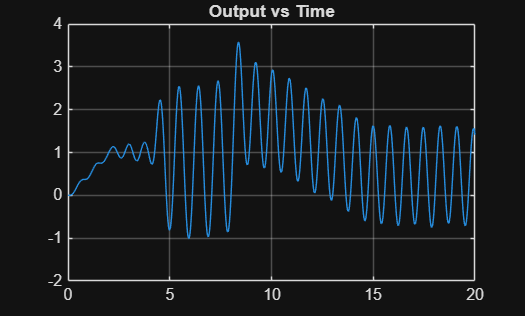


plot(t,y_f)
grid on 
title(" Output vs Time ")

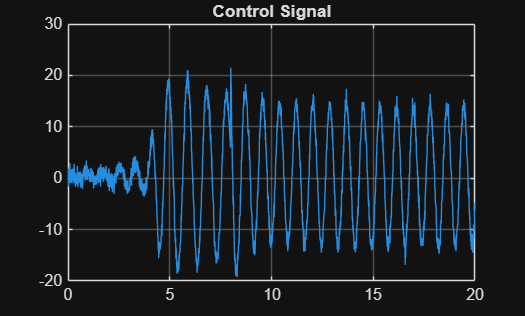


plot(t,u_f)
grid on
title(" Control Signal ")

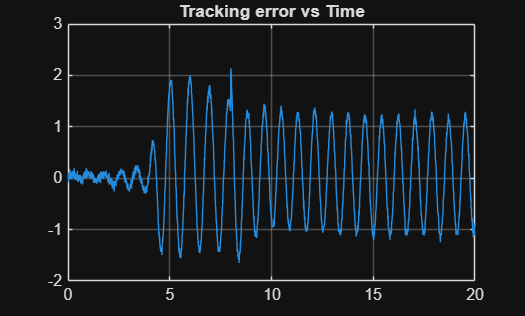


plot(t,e)
grid on
title(" Tracking error vs Time ")


%% Root mean square error
erms = sqrt(mean(e.^2))

erms = 0.8336

Discussing the output of the controller wrt different types of inputs:

- during the ramp the output rises smoothly showing less overshoot and also the refernce and the output are very close can be seen by the error plot that is showing arond zero error at starting .

- Amplitude disbalance can be observed and alsothe error rise is very high during the period .

- the spike is smooth and the ramp down is also smooth , the curve does not loses its stability at any point and the amplitude incresed during the spike and balnced it.

Role of low pass filter:

- Produces smoother control signal.

- Lesser standarad deviation (bar graph shows).

- Redution of the noisy signals by the derived gain introduction.